% Simple-cycle gas turbine burning natural gas.
% C.F. Edwards, 12/19/10
% Dongwon Ka 01/28/2023

clear all
format compact
fprintf('\n****************************************************************\n')


****************************************************************



% Cycle specifications:
global Po To
To = 20+273.15;
Po = oneatm;
global mu_o

% VARY STEAM RATIO
steam_air_ratio = 0.4; % Steam to air ratio for steam injection

T_steam = 500; % Initialize steam injection temp
T_prev = 0;
w = Solution('liquidvapor.yaml','water');
T_steam_in = 293.4056; % Ts2
P_steam_in = 6.3007e6; % Ps2
it = 0;


% ITERATE TO FIND CORRECT STEAM IN TEMP
% 849.03 K is current optimal
%T_steam = 849.03;

if T_steam == 500 % Only Run if T_steam needs to be found
    while abs(T_steam-T_prev)>5e-2
        it = it + 1;
        set(w, "T", T_steam_in, "P", P_steam_in);
        h_steam_in = enthalpy_mass(w);
    
        result = turbineCC(T_steam, steam_air_ratio); % T_out = Tm5
        result.Tm5
        set(w, "T", result.Tm5, "P", P_steam_in);  % ideal case
        h_ideal = enthalpy_mass(w);
        delta_h = 0.85*(h_ideal - h_steam_in);
        
        setState_HP(w, [h_steam_in+delta_h, P_steam_in])
        
        it
        T_prev = T_steam
        T_steam = temperature(w)
        
        hm6 = result.mdot_steam/result.mdot_mix*(result.hs2 - result.hs3) + result.hm5;
        gas = Solution('gri30.yaml');
        set(gas, 'H', hm6, 'P', Po, 'X',result.xmix4);
        xm6_int = exergy_mass(gas);
        Xm6_int = result.mdot_mix*xm6_int;
        xm6_flow = flowExergy_mass(gas);
        Xm6_flow = result.mdot_mix*xm6_flow; 
    end

    T_prev = 0;

end

Ts2 = 293.4056

ans = 630.9806

it = 1

T_prev = 500

T_steam = 552.0301

Ts2 = 293.4056

ans = 965.5648

it = 2

T_prev = 552.0301

T_steam = 727.0634

Ts2 = 293.4056

ans = 963.7612

it = 3

T_prev = 727.0634

T_steam = 725.5814

Ts2 = 293.4056

ans = 963.7602

it = 4

T_prev = 725.5814

T_steam = 725.5806

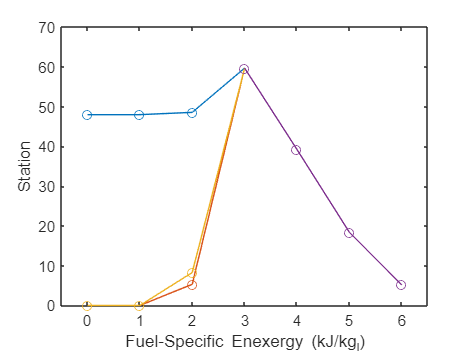


W_net_gas_turbine = result.W_net_gas_turbine; Eff_gas_turbine = result.Eff_gas_turbine; 
Eff_Exergy = result.W_net_gas_turbine/(result.Xf1_flow+result.Xa1_flow);

intExergy_list = [result.Xa1_int result.Xa2_int result.Xf1_int result.Xf2_int result.Xs1_int result.Xs2_int result.Xs3_int result.Xm3_int result.Xm4_int result.Xm5_int Xm6_int]/result.mdot_fuel/1e6;
flowExergy_list = [result.Xa1_flow result.Xa2_flow result.Xf1_flow result.Xf2_flow result.Xs1_flow result.Xs2_flow result.Xs3_flow result.Xm3_flow result.Xm4_flow result.Xm5_flow Xm6_flow]/result.mdot_fuel/1e6;
station_to_mix = [0 1 2 3];
station_from_mix = [3 4 5 6];
fuel_exergy = [intExergy_list(3) intExergy_list(3) intExergy_list(4) intExergy_list(8)];
air_exergy = [intExergy_list(1) intExergy_list(1) intExergy_list(2) intExergy_list(8)];
steam_exergy = [intExergy_list(5) intExergy_list(6) intExergy_list(7) intExergy_list(8)];
mix_exergy = [intExergy_list(8) intExergy_list(9) intExergy_list(10) intExergy_list(11)];
fuel_flowexergy = [flowExergy_list(3) flowExergy_list(3) flowExergy_list(4) flowExergy_list(8)];
air_flowexergy = [flowExergy_list(1) flowExergy_list(1) flowExergy_list(2) flowExergy_list(8)];
steam_flowexergy = [flowExergy_list(5) flowExergy_list(6) flowExergy_list(7) flowExergy_list(8)];
mix_flowexergy = [flowExergy_list(8) flowExergy_list(9) flowExergy_list(10) flowExergy_list(11)];



figure(1)
plot(station_to_mix,air_exergy,'bo-')
hold on
plot(station_to_mix,steam_exergy,'o-','Color',[0 .5 0])
hold on
plot(station_to_mix,fuel_exergy,'ro-')
hold on
plot(station_from_mix,mix_exergy,'ko-')
xlabel('Station')
ylabel('Fuel-Specific Eexergy (MJ/kg_f_u_e_l)')
ylim([0 70])
xlim([-0.5 6.5])

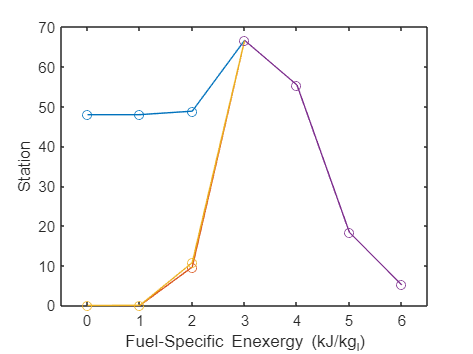

hold off
plotfixer

figure(2)
plot(station_to_mix,air_flowexergy,'bo-')
hold on
plot(station_to_mix,steam_flowexergy,'o-','Color',[0 .5 0])
hold on
plot(station_to_mix,fuel_flowexergy,'ro-')
hold on
plot(station_from_mix,mix_flowexergy,'ko-')
ylabel('Fuel-Specific Flow Eexergy (MJ/kg_f_u_e_l)')
xlabel('Station')
ylim([0 70])
xlim([-0.5 6.5])

hold off
plotfixer

X_des_pump_comp = (result.Xs1_flow-result.Xs2_flow+result.W_steam_compressor);
X_des_fuel_comp = (result.Xf1_flow-result.Xf2_flow+result.W_fuel_compressor);                   % Destroyed exergy at fuel compressor
X_des_air_comp  = (result.Xa1_flow-result.Xa2_flow+result.W_air_compressor);                    % Destroy exergy at air compressor
X_des_premixer  = (result.Xf2_flow+result.Xa2_flow+result.Xs3_flow-result.Xm3_flow);                            % Destroyed exergy at premixer
X_des_combustor = (result.Xm3_flow-result.Xm4_flow);                                     % Destroyed exergy at combustor
X_des_turbine   = (result.Xm4_flow-result.Xm5_flow-result.W_gross_gas_turbine);                 % Destroyed exergy at turbine
X_des_HRSG      = (result.Xm5_flow+result.Xs2_flow-Xm6_flow-result.Xs3_flow);

Unrecognized field name "Xm6_flow".

X_des_exhaust   = Xm6_flow;
X_des_list      = [X_des_pump_comp X_des_fuel_comp X_des_air_comp X_des_premixer X_des_combustor X_des_turbine X_des_HRSG X_des_exhaust];
X_des_list      = X_des_list/sum(X_des_list)*100;

figure(3)
X_bar = categorical({'1', '2', '3', '4', '5', '6','7','8'});
X_bar = reordercats(X_bar,{'1', '2', '3', '4', '5', '6','7','8'});
bar(X_bar, X_des_list)
xlabel("Conversion Device")
ylabel("Exergy Loss (%)")
ylim([0 50])
text(0.3,45,sprintf('Efficiency (LHV) : %.1f%%', Eff_gas_turbine*100))
text(0.3,40,sprintf('Exergy Efficiency: %.1f%%', Eff_Exergy*100))
%text(30,1750,sprintf('Thermal Efficiency:  %.1f%% (LHV)',100*Eff_gas_turbine))
text(0.3,35,sprintf('Device Key:'))
text(0.4,31,sprintf('1-Feed Pump'))
text(0.4,27,sprintf('2-Fuel Compressor'))
text(0.4,23,sprintf('3-Air Compressor'))
text(0.4,19,sprintf('4-Premixer'))
text(0.4,15,sprintf('5-Combustor'))
text(0.4,11,sprintf('6-Turbine'))
text(0.4,7,sprintf('7-HRSG'))
text(0.4,3,sprintf('8-Exhaust'))

plotfixer



function result = turbineCC(T_steam, steam_air_ratio)
global mu_o

steps = 200;
% Cycle specifications:
To = 20+273.15;
Po = oneatm;

Pressure_Ratio = 23;   % pressure ratio 23:1
Burner_Pressure_Ratio                 = 0.95;
Air_Compressor_Polytropic_Efficiency  = 0.90;
Fuel_Compressor_Polytropic_Efficiency = 0.90;
Mix_Turbine_Polytropic_Efficiency     = 0.88;
Tmax = 1700;
mdot_air = 1;
mdot_steam = steam_air_ratio*mdot_air;

% Make a gas object to work with in Cantera.
gas   = Solution('gri30.yaml');
N     = nSpecies(gas);
iCH4  = speciesIndex(gas,'CH4');
iC2H6 = speciesIndex(gas,'C2H6');
iC3H8 = speciesIndex(gas,'C3H8');
iCO2  = speciesIndex(gas,'CO2');
iO2   = speciesIndex(gas,'O2');
iN2   = speciesIndex(gas,'N2');
iAR   = speciesIndex(gas, 'AR');
iH2O  = speciesIndex(gas, 'H2O');
M     = molecularWeights(gas);


% Start with RH=50% air at ambient conditions.
water=Solution('liquidvapor.yaml','water');
P_sat_water=satPressure(water,To);
RH=0.5; % 50%
P_H2O=RH*P_sat_water;
xair = zeros(1,N);
xair(iH2O)=P_H2O/Po;
xair(iN2) = (1-xair(iH2O))*0.757223/(1-0.031208);
xair(iO2) = (1-xair(iH2O))*0.202157/(1-0.031208);
xair(iAR) = (1-xair(iH2O))*0.009015/(1-0.031208);
xair(iCO2)= (1-xair(iH2O))*0.000397/(1-0.031208);
Ta1 = To;
Pa1 = Po;

set(gas,'T',Ta1,'P',Pa1,'X',xair);
mu_o = chemPotentials(gas);
M_air = meanMolecularWeight(gas);
sa1 = entropy_mass(gas);
ha1 = enthalpy_mass(gas);
Sa1 = sa1*mdot_air;
xa1_int = exergy_mass(gas);   %%%%%%%%%%%%%%%%% f1 specific internal exergy 
Xa1_int = mdot_air*xa1_int;
xa1_flow = flowExergy_mass(gas);
Xa1_flow = mdot_air*xa1_flow;

% The second air point is at high pressure.
% Walk up in pressure adjusting via the polytropic efficiency.
Pa2 = Pa1*Pressure_Ratio/Burner_Pressure_Ratio;
dP  = (Pa2 - Pa1)/steps;
s   = sa1;
h   = ha1;
for P = Pa1:dP:Pa2
    % Find the isentropic state at this pressure.
    set(gas,'S',s,'P',P);
    % Get the isentropic enthalpy difference (reversible work).
    hs = enthalpy_mass(gas);
    dhs = hs -h; 
    % The actual enthalpy difference is higher due to inefficiency.
    h = h + dhs/Air_Compressor_Polytropic_Efficiency;
    % Find the actual state at this pressure.
    set(gas,'H',h,'P',P);
    % Save the entropy for the next step in pressure.
    s = entropy_mass(gas);
end
Ta2 = temperature(gas);
ha2 = h;
sa2 = s;
Sa2 = sa2*mdot_air;
xa2_int = exergy_mass(gas);  %%%%%%%%%%%%%%%% f2 specific internal exergy
Xa2_int = mdot_air*xa2_int;
xa2_flow = flowExergy_mass(gas);
Xa2_flow = mdot_air*xa2_flow;

% Start with fuel at ambient conditions.
xfuel = zeros(1,N);
xfuel(iCH4)  = 0.907;
xfuel(iC2H6) = 0.036;
xfuel(iC3H8) = 0.019;
xfuel(iN2)   = 0.018;
xfuel(iCO2)  = 0.010;
xfuel(iO2)   = 0.010;

Tf1 = To;
Pf1 = Po;
set(gas,'T',Tf1,'P',Pf1,'X',xfuel);
M_fuel = meanMolecularWeight(gas);
sf1 = entropy_mass(gas);
hf1 = enthalpy_mass(gas);
xf1_int = exergy_mass(gas);
xf1_flow = flowExergy_mass(gas);
LHV_fuel = 4.613112845315264e+07;

% The second fuel point is at high pressure (twice combustor pressure).
% Walk up in pressure adjusting via the polytropic efficiency.
Pf2 = 2*Pa2;
dP  = (Pf2 - Pf1)/steps;
s   = sf1;
h   = hf1;
for P = Pf1:dP:Pf2
    % Find the isentropic state at this pressure.
    set(gas,'S',s,'P',P);
    % Get the isentropic enthalpy difference (reversible work).
    hs = enthalpy_mass(gas);
    dhs = hs -h; 
    % The actual enthalpy difference is higher due to inefficiency.
    h = h + dhs/Fuel_Compressor_Polytropic_Efficiency;
    % Find the actual state at this pressure.
    set(gas,'H',h,'P',P);
    % Save the entropy for the next step in pressure.
    s = entropy_mass(gas);
end
Tf2 = temperature(gas);
hf2 = h;
sf2 = s;
xf2_int = exergy_mass(gas);
xf2_flow = flowExergy_mass(gas);

% Water Compressor
steam = Solution('liquidvapor.yaml','water');
M_steam = meanMolecularWeight(steam);
Ps1 = Po;
Ts1 = To;
set(steam, "T", Ts1, "P", Ps1)
hs1 = enthalpy_mass(steam);
xs1_int = exergy_mass(steam);  % int exergy
Xs1_int = mdot_steam*xs1_int;  
xs1_flow = flowExergy_mass(steam);
Xs1_flow = mdot_steam*xs1_flow;  


Ps2 = Pf2/(0.92*0.92*0.92); % Pressure drop over HRSG
% Polytropic Pump
dP  = (Ps2 - Ps1)/steps;
s   = entropy_mass(steam);
h   = enthalpy_mass(steam);
for P = Ps1:dP:Ps2
    % Find the isentropic state at this pressure.
    set(steam,'S',s,'P',P);
    % Get the isentropic enthalpy difference (reversible work).
    hs = enthalpy_mass(steam);
    dhs = hs -h; 
    % The actual enthalpy difference is higher due to inefficiency.
    h = h + dhs/Fuel_Compressor_Polytropic_Efficiency;
    % Find the actual state at this pressure.
    set(steam,'H',h,'P',P);
    % Save the entropy for the next step in pressure.
    s = entropy_mass(steam);
end
Ts2 = temperature(steam)
hs2 = h;
ss2 = s;
xs2_int = exergy_mass(steam);               % int exergy
Xs2_int = mdot_steam*xs2_int;  % int exergy
xs2_flow = flowExergy_mass(steam);
Xs2_flow = mdot_steam*xs2_flow;


% Superheat Water
Ps3 = Ps2;
Ts3 = T_steam;
set(steam, "T", Ts3, "P",Ps3);
hs3 = enthalpy_mass(steam);
ss3 = entropy_mass(steam);
xs3_int = exergy_mass(steam);               % int exergy
Xs3_int = mdot_steam*xs3_int;  % int exergy
xs3_flow = flowExergy_mass(steam);
Xs3_flow = mdot_steam*xs3_flow;


% Vary the fuel flow rate (at fixed air flow rate) to find the rate that
% gives the correct turbine inlet temperature.

% Choose a small step in fuel.
dfuel = (mdot_air/15)/2000;
for mdot_fuel=dfuel:dfuel:mdot_air
    mdot_mix = mdot_air + mdot_fuel + mdot_steam;
    Sf1 = sf1*mdot_fuel;
    Sf2 = sf2*mdot_fuel;

    % Mix the air and fuel adiabatically.
    Pm3 = Pa2;
    hm3 = (mdot_fuel*hf2 + mdot_air*ha2 + mdot_steam*hs3)/mdot_mix;
    xmix = xfuel*mdot_fuel/M_fuel;
    xmix = xmix + xair*mdot_air/M_air;
    xmix(iH2O) = xmix(iH2O) + mdot_steam/M_steam;
    xmix = xmix/sum(xmix);
    set(gas,'H',hm3,'P',Pm3,'X',xmix);
    Tm3 = temperature(gas);
    sm3 = entropy_mass(gas);
    Sm3 = sm3*mdot_mix;
    xm3_int = exergy_mass(gas);
    Xm3_int = mdot_mix*xm3_int;       %%%%%%%%%%%%%%%% m3 internal exergy
    xm3_flow = flowExergy_mass(gas);
    Xm3_flow = mdot_mix*xm3_flow;

    % Burn the mixture adiabatically.
    Pm4 = Pm3*Burner_Pressure_Ratio;
    set(gas,'H',hm3,'P',Pm4);
    equilibrate(gas,'HP');
    Tm4 = temperature(gas);
    
    % Look for a simple crossover since the steps are small and fast.
    if(Tm4 >= Tmax)
        Tpeak = Tm4;
        break
    end
end
sm4 = entropy_mass(gas);
hm4 = enthalpy_mass(gas);
Sm4 = sm4*mdot_mix;

xmix4(:) = moleFractions(gas);          %%%%%%%%% moleFractions after combustion
xm4_int = exergy_mass(gas);
Xm4_int = mdot_mix*xm4_int;           %%%% m4 internal exergy
xm4_flow = flowExergy_mass(gas);
Xm4_flow = mdot_mix*xm4_flow;

Xf1_int = mdot_fuel*xf1_int;       %%%% f1 f2 internal exergy
Xf2_int = mdot_fuel*xf2_int;
Xf1_flow = mdot_fuel*xf1_flow;        %%%%% f1 f2 flow exergy
Xf2_flow = mdot_fuel*xf2_flow;

% Expand the products.  Use small steps and polytropic efficiency.
Pm5 = Po;
dP  = (Pm4 - Pm5)/steps;
s   = sm4;
h   = hm4;
for P = Pm4:-dP:Pm5
    % Find the starting state for the step.
    set(gas,'S',s,'P',P);
    % Find the isentropic enthapy change.
    hs = enthalpy_mass(gas);
    dhs = h - hs;
    % The actual change is less due to inefficiency.
    h = h - dhs*Mix_Turbine_Polytropic_Efficiency;
    % Find the actual state.
    set(gas,'H',h,'P',P);
    % Include the next line for shifting equilibrium.  Remove if you prefer
    % to leave the gas frozen in composition.  (A small difference.)
    equilibrate(gas,'HP');
    % Get the entropy for the next step.
    s = entropy_mass(gas);
end
Tm5 = temperature(gas);
hm5 = h;
sm5 = s;
Sm5 = sm5*mdot_mix;

xm5_int = exergy_mass(gas);       %%%% f1 f2 internal exergy
Xm5_int = mdot_mix*xm5_int;
xm5_flow = flowExergy_mass(gas);        %%%%% f1 f2 flow exergy
Xm5_flow = mdot_mix*xm5_flow;

% Find the various energy transfers.
Air_Fuel_Mass_Ratio = mdot_air/mdot_fuel;
W_fuel_compressor   = mdot_fuel*(hf2 - hf1);
W_air_compressor    = mdot_air*(ha2 - ha1);
W_steam_compressor  = mdot_steam*(hs2 - hs1);
W_gross_gas_turbine = mdot_mix*(hm4 - hm5);
W_net_gas_turbine   = W_gross_gas_turbine - W_fuel_compressor - W_air_compressor - W_steam_compressor;
Eff_gas_turbine     = W_net_gas_turbine/(mdot_fuel*LHV_fuel);                        % 1st law efficieny to LHV
Air_Specific_Work   = W_net_gas_turbine/mdot_air;
%Eff_exergy        = W_net_gas_turbine/(Xf1_flow+Xa1_flow+Xs1_flow-Xm6_flow);             % Exergy efficiency

result.W_net_gas_turbine = W_net_gas_turbine; 
result.Eff_gas_turbine = Eff_gas_turbine; 
result.W_gross_gas_turbine = W_gross_gas_turbine;
result.W_fuel_compressor = W_fuel_compressor; 
result.W_air_compressor = W_air_compressor; 
result.W_steam_compressor = W_steam_compressor; 

result.xa1_int = xa1_int; result.Xa1_int = Xa1_int; result.xa1_flow = xa1_flow; result.Xa1_flow = Xa1_flow;
result.xa2_int = xa2_int; result.Xa2_int = Xa2_int; result.xa2_flow = xa2_flow; result.Xa2_flow = Xa2_flow;
result.xf1_int = xf1_int; result.Xf1_int = Xf1_int; result.xf1_flow = xf1_flow; result.Xf1_flow = Xf1_flow;
result.xf2_int = xf2_int; result.Xf2_int = Xf2_int; result.xf2_flow = xf2_flow; result.Xf2_flow = Xf2_flow;
result.xs1_int = xs1_int; result.Xs1_int = Xs1_int;
result.xs2_int = xs2_int; result.Xs2_int = Xs2_int;
result.xs3_int = xs3_int; result.Xs3_int = Xs3_int;
result.xs1_flow = xs1_flow; result.Xs1_flow = Xs1_flow;
result.xs2_flow = xs2_flow; result.Xs2_flow = Xs2_flow;
result.xs3_flow = xs3_flow; result.Xs3_flow = Xs3_flow;
result.xm3_int = xm3_int; result.Xm3_int = Xm3_int;
result.xm4_int = xm4_int; result.Xm4_int = Xm4_int;
result.xm5_int = xm5_int; result.Xm5_int = Xm5_int;
result.xm3_flow = xm3_flow; result.Xm3_flow = Xm3_flow;
result.xm4_flow = xm4_flow; result.Xm4_flow = Xm4_flow;
result.xm5_flow = xm5_flow; result.Xm5_flow = Xm5_flow;
result.mdot_mix = mdot_mix; result.mdot_steam = mdot_steam; result.mdot_fuel = mdot_fuel;
result.hs2 = hs2; result.hs3 = hs3; result.hm5 = hm5;
result.Tm5 = Tm5;
result.xmix4 = xmix4;

end % end of whole





















function turbineGraph(T_steam, steam_air_ratio)

steps = 200;
% Cycle specifications:
To = 20+273.15;
Po = oneatm;

Pressure_Ratio = 23;   % pressure ratio 23:1
Burner_Pressure_Ratio                 = 0.95;
Air_Compressor_Polytropic_Efficiency  = 0.90;
Fuel_Compressor_Polytropic_Efficiency = 0.90;
Mix_Turbine_Polytropic_Efficiency     = 0.88;
Tmax = 1700;
mdot_air = 1;
mdot_steam = steam_air_ratio*mdot_air;

% Make a gas object to work with in Cantera.
gas   = Solution('gri30.yaml');
N     = nSpecies(gas);
iCH4  = speciesIndex(gas,'CH4');
iC2H6 = speciesIndex(gas,'C2H6');
iC3H8 = speciesIndex(gas,'C3H8');
iCO2  = speciesIndex(gas,'CO2');
iO2   = speciesIndex(gas,'O2');
iN2   = speciesIndex(gas,'N2');
iAR   = speciesIndex(gas, 'AR');
iH2O  = speciesIndex(gas, 'H2O');
M     = molecularWeights(gas);


% Start with RH=50% air at ambient conditions.
water=Solution('liquidvapor.yaml','water');
P_sat_water=satPressure(water,To);
RH=0.5; % 50%
P_H2O=RH*P_sat_water;
xair = zeros(1,N);
xair(iH2O)=P_H2O/Po;
xair(iN2) = (1-xair(iH2O))*0.757223/(1-0.031208);
xair(iO2) = (1-xair(iH2O))*0.202157/(1-0.031208);
xair(iAR) = (1-xair(iH2O))*0.009015/(1-0.031208);
xair(iCO2)= (1-xair(iH2O))*0.000397/(1-0.031208);
Ta1 = To;
Pa1 = Po;
set(gas,'T',Ta1,'P',Pa1,'X',xair);
M_air = meanMolecularWeight(gas);
sa1 = entropy_mass(gas);
ha1 = enthalpy_mass(gas);
Sa1 = sa1*mdot_air;

Xa1_int = mdot_air*intExergy_mass(xair, Ta1, Pa1, xair);         %%%%%%%%%%%%%%%%%%%%% a1 internal exergy
Xa1_flow = mdot_air*flowExergy_mass(xair, Ta1, Pa1, xair);

% The second air point is at high pressure.
% Walk up in pressure adjusting via the polytropic efficiency.
Pa2 = Pa1*Pressure_Ratio/Burner_Pressure_Ratio;
dP  = (Pa2 - Pa1)/steps;
s   = sa1;
h   = ha1;
for P = Pa1:dP:Pa2
    % Find the isentropic state at this pressure.
    set(gas,'S',s,'P',P);
    % Get the isentropic enthalpy difference (reversible work).
    hs = enthalpy_mass(gas);
    dhs = hs -h; 
    % The actual enthalpy difference is higher due to inefficiency.
    h = h + dhs/Air_Compressor_Polytropic_Efficiency;
    % Find the actual state at this pressure.
    set(gas,'H',h,'P',P);
    % Save the entropy for the next step in pressure.
    s = entropy_mass(gas);
end
Ta2 = temperature(gas);
ha2 = h;
sa2 = s;
Sa2 = sa2*mdot_air;
Xa2_int = mdot_air*intExergy_mass(xair, Ta2, Pa2, xair);  %%%%%%%%%%%%%%%%%%%%%%% a2 internal exergy
Xa2_flow = mdot_air*flowExergy_mass(xair, Ta2, Pa2, xair); % a2 flow exergy

% Find the isentropic efficiency for this pressure ratio just for fun.
set(gas,'S',sa1,'P',Pa2);
ha2s = enthalpy_mass(gas);
Air_Compressor_Isentropic_Efficiency = (ha2s - ha1)/(ha2 - ha1);


% Start with fuel at ambient conditions.
xfuel = zeros(1,N);
xfuel(iCH4)  = 0.907;
xfuel(iC2H6) = 0.036;
xfuel(iC3H8) = 0.019;
xfuel(iN2)   = 0.018;
xfuel(iCO2)  = 0.010;
xfuel(iO2)   = 0.010;

% Find the lower heating value of the fuel.  Use extra oxygen to ensure
% complete combustion.  Since To is so low, dissociation is not an issue.
% Note that some versions of Cantera can't do 25C so use 300K.  Ug!
Nfuel = xfuel;                  % Use one mole of fuel
Noxid = 10;                     % Use excess oxygen (>2 for methane)
Nmix = Nfuel;                   % Put it in the mixture
Nmix(iO2) = Nmix(iO2) + Noxid;  % Add oxygen in excess of requirements
mass_mix = 0;                   % Find the mass of the mixture
for i=1:1:N
    mass_mix = mass_mix + Nmix(i)*M(i);
end
mass_fraction_O2 = Noxid*M(iO2)/mass_mix;   % Get the fraction of oxid
mass_fraction_fuel = 1 - mass_fraction_O2;  % Get the fraction of fuel

set(gas,'T',300,'P',101325,'X',Nmix);       % Put in the mixture
h_reactants = enthalpy_mass(gas);           % Find its enthalpy
equilibrate(gas,'TP');                      % Burn it at constant TP
h_products = enthalpy_mass(gas);            % Find the enthalpy
LHV_fuel = (h_reactants - h_products)/mass_fraction_fuel;    % Get LHV (mass)


Tf1 = To;
Pf1 = Po;
set(gas,'T',Tf1,'P',Pf1,'X',xfuel);
M_fuel = meanMolecularWeight(gas);
sf1 = entropy_mass(gas);
hf1 = enthalpy_mass(gas);
xf1_int = intExergy_mass(xfuel, Tf1, Pf1, xair);   %%%%%%%%%%%%%%%%% f1 specific internal exergy 
xf1_flow = flowExergy_mass(xfuel, Tf1, Pf1, xair);


% The second fuel point is at high pressure (twice combustor pressure).
% Walk up in pressure adjusting via the polytropic efficiency.
Pf2 = 2*Pa2;
dP  = (Pf2 - Pf1)/steps;
s   = sf1;
h   = hf1;
for P = Pf1:dP:Pf2
    % Find the isentropic state at this pressure.
    set(gas,'S',s,'P',P);
    % Get the isentropic enthalpy difference (reversible work).
    hs = enthalpy_mass(gas);
    dhs = hs -h; 
    % The actual enthalpy difference is higher due to inefficiency.
    h = h + dhs/Fuel_Compressor_Polytropic_Efficiency;
    % Find the actual state at this pressure.
    set(gas,'H',h,'P',P);
    % Save the entropy for the next step in pressure.
    s = entropy_mass(gas);
end
Tf2 = temperature(gas);
hf2 = h;
sf2 = s;
xf2_int = intExergy_mass(xfuel, Tf2, Pf2, xair);  %%%%%%%%%%%%%%%% f2 specific internal exergy
xf2_flow = flowExergy_mass(xfuel, Tf2, Pf2, xair);

% Find the isentropic efficiency for this pressure ratio just for fun.
set(gas,'S',sf1,'P',Pf2);
hf2s = enthalpy_mass(gas);
Fuel_Compressor_Isentropic_Efficiency = (hf2s - hf1)/(hf2 - hf1);

% Water Compressor
steam = Solution('liquidvapor.yaml','water');
M_steam = meanMolecularWeight(steam);
Ps1 = Po;
Ts1 = To;
set(steam, "T", Ts1, "P", Ps1)
xs1_int = intExergy_mass(xsteam, Ts1, Ps1, xair);
xs1_flow = flowExergy_mass(xsteam, Ts1, Ps1, xair);
Xs1_int = mdot_steam*xs1_int;
Xs1_flow = mdot_steam*xs1_flow;

Ps2 = Pf2/(0.92*0.92*0.92); % Pressure drop over HRSG
% Polytropic Pump
dP  = (Ps2 - Ps1)/steps;
s   = entropy_mass(steam);
h   = enthalpy_mass(steam);
for P = Ps1:dP:Ps2
    % Find the isentropic state at this pressure.
    set(steam,'S',s,'P',P);
    % Get the isentropic enthalpy difference (reversible work).
    hs = enthalpy_mass(steam);
    dhs = hs -h; 
    % The actual enthalpy difference is higher due to inefficiency.
    h = h + dhs/Fuel_Compressor_Polytropic_Efficiency;
    % Find the actual state at this pressure.
    set(steam,'H',h,'P',P);
    % Save the entropy for the next step in pressure.
    s = entropy_mass(steam);
end
Ts2 = temperature(steam)
hs2 = h;
ss2 = s;
xs2_int = intExergy_mass(xsteam, Ts2, Ps2, xair);  %%%%%%%%%%%%%%%% s2 specific internal exergy
xs2_flow = flowExergy_mass(xsteam, Ts2, Ps2, xair);
Xs2_int = mdot_steam*xs2_int;
Xs2_flow = mdot_steam*xs2_flow;

% Superheat Water
Ps3 = Ps2;
Ts3 = T_steam;
set(steam, "T", Ts3, "P",Ps3);
hs3 = enthalpy_mass(steam);
ss3 = entropy_mass(steam);
xs3_int = intExergy_mass(xsteam, Ts3, Ps3, xair);  %%%%%%%%%%%%%%%% s2 specific internal exergy
xs3_flow = flowExergy_mass(xsteam, Ts3, Ps3, xair);
Xs3_int = mdot_steam*xs3_int;
Xs3_flow = mdot_steam*xs3_flow;

% Vary the fuel flow rate (at fixed air flow rate) to find the rate that
% gives the correct turbine inlet temperature.

% Choose a small step in fuel.
dfuel = (mdot_air/15)/2000;
for mdot_fuel=dfuel:dfuel:mdot_air
    mdot_mix = mdot_air + mdot_fuel + mdot_steam;
    Sf1 = sf1*mdot_fuel;
    Sf2 = sf2*mdot_fuel;

    % Mix the air and fuel adiabatically.
    Pm3 = Pa2;
    hm3 = (mdot_fuel*hf2 + mdot_air*ha2 + mdot_steam*hs3)/mdot_mix;
    xmix = xfuel*mdot_fuel/M_fuel;
    xmix = xmix + xair*mdot_air/M_air;
    xmix(iH2O) = xmix(iH2O) + mdot_steam/M_steam;
    xmix = xmix/sum(xmix);
    set(gas,'H',hm3,'P',Pm3,'X',xmix);
    Tm3 = temperature(gas);
    sm3 = entropy_mass(gas);
    Sm3 = sm3*mdot_mix;
  
    % Burn the mixture adiabatically.
    Pm4 = Pm3*Burner_Pressure_Ratio;
    set(gas,'H',hm3,'P',Pm4);
    h_reactants = enthalpy_mass(gas);
    equilibrate(gas,'HP');
    h_products = enthalpy_mass(gas);
    LHV_fuel = (h_reactants - h_products)/mass_fraction_fuel; % do we have mass fraction?
    Tm4 = temperature(gas);
    
    % Look for a simple crossover since the steps are small and fast.
    if(Tm4 >= Tmax)
        Tpeak = Tm4;
        break
    end
end
sm4 = entropy_mass(gas);
hm4 = enthalpy_mass(gas);
Sm4 = sm4*mdot_mix;

Xm3_int = mdot_mix*intExergy_mass(xmix, Tm3, Pm3, xair);       %%%%%%%%%%%%%%%% m3 internal exergy
Xm3_flow = mdot_mix*flowExergy_mass(xmix, Tm3, Pm3, xair);

xmix4(:) = moleFractions(gas);                                     %%%%%%%%%%%%%%%%%% moleFractions after combustion
Xm4_int = mdot_mix*intExergy_mass(xmix4, Tm4, Pm4, xair);            %%%%%%%%%%%%%%%%%%% m4 internal exergy
Xm4_flow = mdot_mix*flowExergy_mass(xmix4, Tm4, Pm4, xair);

Xf1_int = mdot_fuel*xf1_int;                                          %%%%%%%%%%%%%%%%%% f1 f2 internal exergy
Xf2_int = mdot_fuel*xf2_int;
Xf1_flow = mdot_fuel*xf1_flow;                                          %%%%%%%%%%%%%%%%%% f1 f2 flow exergy
Xf2_flow = mdot_fuel*xf2_flow;


% Expand the products.  Use small steps and polytropic efficiency.
Pm5 = Po;
dP  = (Pm4 - Pm5)/steps;
s   = sm4;
h   = hm4;
for P = Pm4:-dP:Pm5
    % Find the starting state for the step.
    set(gas,'S',s,'P',P);
    % Find the isentropic enthapy change.
    hs = enthalpy_mass(gas);
    dhs = h - hs;
    % The actual change is less due to inefficiency.
    h = h - dhs*Mix_Turbine_Polytropic_Efficiency;
    % Find the actual state.
    set(gas,'H',h,'P',P);
    % Include the next line for shifting equilibrium.  Remove if you prefer
    % to leave the gas frozen in composition.  (A small difference.)
    equilibrate(gas,'HP');
    % Get the entropy for the next step.
    s = entropy_mass(gas);
end
Tm5 = temperature(gas);
hm5 = h;
sm5 = s;
Sm5 = sm5*mdot_mix;

xmix5=xmix4;
Xm5_int = mdot_mix*intExergy_mass(xmix5, Tm5, Pm5, xair);                %%%%%%%%%%%%%%%%%%%%% m5 internal exergy
Xm5_flow = mdot_mix*flowExergy_mass(xmix5, Tm5, Pm5, xair);

% Assemble an array of state points.
Tair  = [Ta1 Ta2];
Pair  = [Pa1 Pa2];
Sair  = [Sa1 Sa2];
Tfuel = [Tf1 Tf2];
Pfuel = [Pf1 Pf2];
Sfuel = [Sf1 Sf2];
Tmix  = [Tm4 Tm5];
Pmix  = [Pm4 Pm5];
Smix  = [Sm4 Sm5];

% Exergy List
x_int = [Xf1_int Xf2_int Xa1_int Xa2_int Xm3_int Xm4_int Xm5_int]/mdot_fuel;      % semi-extensive internal exergy
x_flow = [Xf1_flow Xf2_flow Xa1_flow Xa2_flow Xm3_flow Xm4_flow Xm5_flow]/mdot_fuel;
X_int = [Xf1_int Xf2_int Xa1_int Xa2_int Xm3_int Xm4_int Xm5_int];                % extensive exergy lists
X_flow = [Xf1_flow Xf2_flow Xa1_flow Xa2_flow Xm3_flow Xm4_flow Xm5_flow];

% Find the various energy transfers.
Air_Fuel_Mass_Ratio = mdot_air/mdot_fuel;
W_fuel_compressor   = mdot_fuel*(hf2 - hf1);
W_air_compressor    = mdot_air*(ha2 - ha1);
W_gross_gas_turbine = mdot_mix*(hm4 - hm5);
W_steam_compressor  = mdot_steam*(hs2-hs1);
W_net_gas_turbine   = W_gross_gas_turbine - W_fuel_compressor - W_air_compressor - W_steam_compressor;
Eff_gas_turbine     = W_net_gas_turbine/(mdot_fuel*LHV_fuel);                        % 1st law efficieny to LHV
Air_Specific_Work   = W_net_gas_turbine/mdot_air;

Eff_exergy        = W_net_gas_turbine/(Xf1_flow+Xa1_flow-Xm5_flow);             % Exergy efficiency

% Extensive exergy analysis
X_des_total     = Xf1_flow+Xa1_flow-W_net_gas_turbine;
X_des_fuel_comp = (Xf1_flow-Xf2_flow+W_fuel_compressor)/X_des_total*100;                   % Destroyed exergy at fuel compressor
X_des_air_comp  = (Xa1_flow-Xa2_flow+W_air_compressor)/X_des_total*100;                    % Destroy exergy at air compressor
X_des_premixer  = (Xf2_flow+Xa2_flow-Xm3_flow)/X_des_total*100;                            % Destroyed exergy at premixer
X_des_combustor = (Xm3_flow-Xm4_flow)/X_des_total*100;                                     % Destroyed exergy at combustor
X_des_turbine   = (Xm4_flow-Xm5_flow-W_gross_gas_turbine)/X_des_total*100;                 % Destroyed exergy at turbine
X_des_exhaust   = Xm5_flow/X_des_total*100;
X_des_list      = [X_des_fuel_comp X_des_air_comp X_des_premixer X_des_combustor X_des_turbine X_des_exhaust];

% Fuel- Specific Exergy Plot
plot(1:3,[Xf1_flow Xf2_flow Xm3_flow]./(1e6*mdot_fuel), "ro-")
hold on
plot(1:3,[Xa1_flow Xa2_flow Xm3_flow]./(1e6*mdot_fuel), "bo-")
plot(3:5,[Xm3_flow Xm4_flow Xm5_flow]./(1e6*mdot_fuel), "go-")
legend(["Fuel", "Air", "Mix"])
xlabel("Station")
ylabel("Fuel-Specific Exergy [MJ/kg-fuel]")
improvePlot
hold off

% Internal Version
plot(1:3,[Xf1_int Xf2_int Xm3_int]./(1e6*mdot_fuel), "ro-")
hold on
plot(1:3,[Xa1_int Xa2_int Xm3_int]./(1e6*mdot_fuel), "bo-")
plot(3:5,[Xm3_int Xm4_int Xm5_int]./(1e6*mdot_fuel), "go-")
legend(["Fuel", "Air", "Mix"])
xlabel("Station")
ylabel("Internal Fuel-Specific Exergy [MJ/kg-fuel]")
improvePlot
hold off

%Exergy Destruction Plot
X_bar = categorical({'Fuel \n Compressor', 'Air \n Compressor', 'Premixer', 'Combustor', 'Turbine', 'Exhaust'});
X_bar = reordercats(X_bar,{'Fuel \n Compressor', 'Air \n Compressor', 'Premixer', 'Combustor', 'Turbine', 'Exhaust'});
bar(X_bar, X_des_list)
xlabel("Conversion Device")
ylabel("Flow Exergy Loss [%]")
text(1,30,['LHV Efficiency: ' string(Eff_gas_turbine)])
text(1,20,['Exergy Efficiency: ' string(Eff_exergy)])

end % end of whole



% function internal_exergy=intExergy_mass(x_gas, T_gas, P_gas, x_dead)
%     global To
%     global Po
%     
%     gas=Solution('gri30.yaml');
%     M_gri=molecularWeights(gas);    
%     nsp = nSpecies(gas);
%     iO2 = speciesIndex(gas, 'O2');
%     iCO2 = speciesIndex(gas, 'CO2');
%     iH2O = speciesIndex(gas, 'H2O');
%     iN2 = speciesIndex(gas, 'N2');
%     iAR = speciesIndex(gas, 'AR');
% 
%     set(gas,'P',P_gas,'T',T_gas,'X',x_gas);
%     u1=intEnergy_mass(gas);
%     v1=1/density(gas);
%     s1=entropy_mass(gas);
%     a1=u1+Po*v1-To*s1;  % Availability function per mass
% 
%     set(gas,'P',Po,'T',To,'X',x_gas);
%     u0=intEnergy_mass(gas);
%     v0=1/density(gas);
%     s0=entropy_mass(gas);
%     g_TM=u0+Po*v0-To*s0;  % Gibbs function in TM dead state
% 
%     for i=1:nsp
%         x_test=zeros(nsp,1);
%         x_test(i)=1;
%         set(gas,'P',Po,'T',To,'X',x_test); % dead, but the potential should be found from the gas composition
%         chem_P_test=chemPotentials(gas)/1000; % [J/mol]
%         chem_P(i)=chem_P_test(i);
%     end
%     %chem_P=chemPotentials(gas)/1000; % [J/mol]
%     R=8.31; % [J/mol/K]
%         
%     nH=zeros(nsp,1); nC=zeros(nsp,1); nO=zeros(nsp,1); nAR=zeros(nsp,1); nN=zeros(nsp,1);
%     set(gas,'P',Po,'T',To,'X',x_gas);
%     for i=1:nsp
%         % A reactant species atoms
%         nH(i)=nAtoms(gas,i,'H');
%         nO(i)=nAtoms(gas,i,'O');
%         nC(i)=nAtoms(gas,i,'C');
%         nAR(i)=nAtoms(gas,i,'Ar');
%         nN(i)=nAtoms(gas,i,'N');
%        
%         % products moles from the reactant
%         nCO2(i)=nC(i); nN2(i)=0.5*nN(i); nH2O(i)=0.5*nH(i); nAR(i)=nAR(i); nO2(i)=0.5*(nO(i)-2*nCO2(i)-nH2O(i));
%         
%     end
%     
%     chem_P_TM=zeros(nsp,1); chem_P_0=zeros(nsp,1);
%     for i=1:nsp
%         if x_gas(i)~=0
%             chem_P_TM(i)=chem_P(i)+R*To*log(x_gas(i));  % [J/mol]   
%         end
%         if x_dead(i)~=0
%             chem_P_0(i)=chem_P(i)+R*To*log(x_dead(i));  % [J/mol]
%         end
%     end
%     
%     x_chem_species=zeros(nsp,1); x_TM=zeros(nsp,1);
%     for i=1:nsp
%         if x_gas(i)~=0
%             x_chem_species(i)=(chem_P_TM(i)-(nO2(i)*chem_P_0(iO2)+nCO2(i)*chem_P_0(iCO2)+nH2O(i)*chem_P_0(iH2O)+nN2(i)*chem_P_0(iN2)+nAR(i)*chem_P_0(iAR)))*x_gas(i);
%             x_TM(i)=chem_P_TM(i)*x_gas(i);
%         end
%     end
%  
%     x_mech_mass=a1-g_TM;
%     x_chem_mole=sum(x_chem_species); %[J/mol]
%     x_TM_mole=sum(x_TM);
%     
% 
%     fuel_mass=x_gas*M_gri/1000; %[kg/mol]
%     x_chem_mass=x_chem_mole/fuel_mass;
%     x_TM_mass=x_TM_mole/fuel_mass; % to see g_TM=x_TM_mass almost the same
%     x_internal_mass=x_mech_mass+x_chem_mass;
%     internal_exergy=x_internal_mass;
% end
% 
% function flow_exergy_mass=flowExergy_mass(x_gas, T_gas, P_gas, x_dead)
%     global To
%     global Po
%     
%     gas=Solution('gri30.yaml');
%     M_gri=molecularWeights(gas);    
% 
%     set(gas,'P',P_gas,'T',T_gas,'X',x_gas);
%     v1=1/density(gas);
% 
%     fuel_mass=x_gas*M_gri/1000; %[kg/mol]
%     int_exergy_mass=intExergy_mass(x_gas, T_gas, P_gas, x_dead);
%     x_internal_mole=int_exergy_mass*fuel_mass; %[J/mol]
%     flow_exergy_mole=(x_internal_mole+(P_gas-Po)*v1*fuel_mass); %[J/mol]
%     flow_exergy_mass=flow_exergy_mole/fuel_mass; %[J/kg]
% end
